G0 = tf(conv([1,3],[1, -1]),conv([1,0],conv([1,-2], [1,-2])))


G0 =
 
    s^2 + 2 s - 3
  -----------------
  s^3 - 4 s^2 + 4 s
 
Continuous-time transfer function.
Model Properties


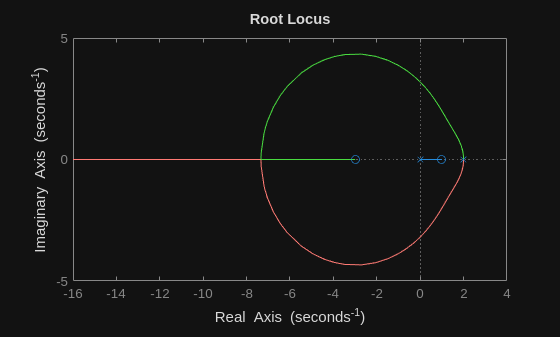

rlocus(G0)

angle(3+2i)

ans = 0.5880

G1 = 15*G0


G1 =
 
  15 s^2 + 30 s - 45
  ------------------
  s^3 - 4 s^2 + 4 s
 
Continuous-time transfer function.
Model Properties


[y,t]= step(G1)

y = 1.0e+26 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


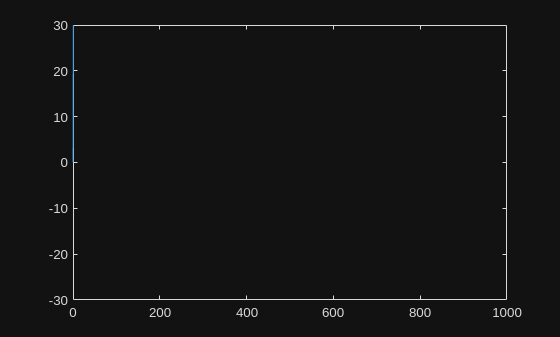


figure
plot(t,y)
xlim([0,1000])
ylim([-30 30])